% write nonAvgIqtau value to a separate file
clc; clear all;
files = dir('*.mat');
for file = files'
    load(file.name);
    disp(file.name)
    nonAvgIqtau = cilia.Results(1).Box(1).NonAvgIqtau;
    qVec = cilia.Results.qVec;
    output_name = [file.name(1:end-4) '_nonAvgIqtau.mat'];
%     disp(output_name)
    save(output_name,'nonAvgIqtau')
end

01.mat
02.mat
03.mat
04.mat
05.mat
06.mat
07.mat
08.mat
09.mat
10.mat
11.mat
12.mat
13.mat
14.mat
15.mat
16.mat
18.mat
19.mat
20.mat
21.mat
22.mat
23.mat
24.mat
25.mat
26.mat
27.mat
28.mat
29.mat
30.mat



% generate directioned Iqtau from nonAvgIqtau files
clc
clear
files = dir('*_nonAvgIqtau.mat');
framerate=10;
path='';

% set masks and distance maps
angle_num=16;
scale=1024;
angle_mask_list=create_angle_mask_list(scale,angle_num);
[distance_map, dist_counts] = create_distance_map(scale);

for file = files'
    load(file.name);
    generate_directioned_Iqtau(angle_mask_list,distance_map,dist_counts,nonAvgIqtau,path,file.name);
end

clc
clear

% filename='deshaked_gray_rescale_crop_fps10_20s_30feet_100000811592 (online-video-cutter.com)_nonAvgIqtau_angle_Iqtau.mat';
filename='large_two_waves_nonAvgIqtau_angle_Iqtau.mat';
path='';
wavelength=100; % pixels
q_max=200;
scale=1024;
plotIq_all_dirc_all_tau(filename,path,wavelength,scale,q_max)

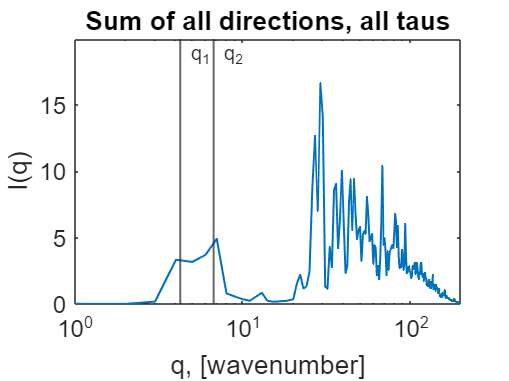

filename='combined_nonAvgIqtau_angle_Iqtau.mat';
path='';
wavelength=100; % pixels
q_max=200;
scale=1024;
plotIq_all_dirc_all_tau(filename,path,wavelength,scale,q_max)

% filename='deshaked_gray_rescale_crop_fps10_20s_30feet_100000811592 (online-video-cutter.com)_nonAvgIqtau.mat';
% filename='combined_nonAvgIqtau.mat';
filename='large_two_waves_nonAvgIqtau.mat';
theta=0;
wavenumber=10;
tau=16;
q_range=10;
plotFFTdifference(filename,theta,wavenumber,scale,q_range,tau,path)